# Mooney-Rivlin material model

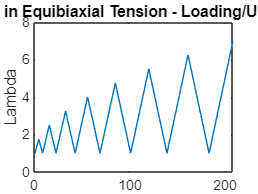

% Stretches for Equibiaxial Tension
s = 4; % No. of points in-between stretches 
k = 1;
lambda = [];
while k <= 6
    lambda_loading = linspace(1, k+0.75, s*k+1);
    lambda_unloading = flip(lambda_loading(2:end-1));
    lambda = [lambda, lambda_loading, lambda_unloading];
    k = k + 0.75;
end
lambda = [lambda, linspace(1, k+0.75, s*k+1)];
lambda = lambda';
plot(lambda);
title("Stretch in Equibiaxial Tension - Loading/Unloading")
ylabel("Lambda")

% EBT Deformation Gradient from the stretch
asize = size(lambda, 1);
F = zeros(asize, 3, 3);
for i = 1:size(lambda)
    F(i, 1, 1) = lambda(i, 1);
    F(i, 2, 2) = lambda(i, 1);
    F(i, 3, 3) = 1/(lambda(i, 1).^2);
end 

% Right Cauchy Green Tensor
C = zeros(asize, 3, 3);
for i = 1:asize
    F_temp = zeros(3, 3);
    F_temp(:, :) = F(i, :, :);
    C(i, :, :) = F_temp' * F_temp;
end

% First and Second Strain Invariants
I = zeros(asize, 1);
II = zeros(asize, 1);
for i = 1:asize
    C_temp = zeros(3, 3);
    C_temp(:, :) = C(i, :, :);
    I(i) = trace(C_temp);
    II(i) = 0.5*(I(i).^2 - (trace(C_temp * C_temp)));
end

Strain Energy Function for the Mooney Rivlin Model is:

% Material Constants (in MPa)
C10 = [0.16, -1.4e-3, 3.9e-5];
C01 = [1.5e-2, -2.0e-6, 1.0e-10];

% Primary Strain Energy Function
U = zeros(asize, 1);
for i = 1:asize
    for j = 1:3
    U(i, 1) = U(i, 1) + C10(1, j)*((I(i, 1) - 3).^j) + C01(1, j)*((II(i, 1) - 3).^j);
    end
end

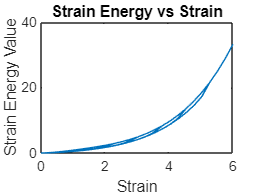

% Other material Constants for the Mullins effect
m = 2;
r = 2;
beta = 0.1;

U_mod = zeros(asize, 1); % modified Strain Energy Function
U_max = U(1, 1); % maximum value reached in loading/unloading
eta = zeros(asize, 1); % Damage Variable
phi = zeros(asize, 1); % Damage function
phi_m = zeros(asize, 1); % Damage function at U_max

% Modified Strain Energy Function
for i = 1:asize
    if U(i, 1) < U_max % unloading path
        eta_min = damage_var(r, beta, m, 0, U_max); % minimum value of damage variable at U_max
        eta(i, 1) = damage_var(r, beta, m, U(i, 1), U_max);
        phi(i, 1) = damage_func(r, beta, m, eta(i, 1), U_max);
        phi_m(i, 1) = damage_func(r, beta, m, eta_min, U_max);
        U_mod(i, 1) = eta(i, 1) * U(i, 1) + phi(i, 1) - phi_m(i, 1);
    else
        U_max = U(i, 1); % primary loading path
        eta(i, 1) = damage_var(r, beta, m, U(i, 1), U_max);
        eta_min   = damage_var(r, beta, m, 0, U_max);
        phi(i, 1) = damage_func(r, beta, m, eta(i, 1), U_max);
        phi_m(i, 1) = damage_func(r, beta, m, eta_min, U_max);
        U_mod(i, 1) = eta(i, 1) * U(i, 1) + phi(i, 1) - phi_m(i, 1);
    end
end

% Plotting the Strain Energy Values vs Stretch
plot(lambda-1, U_mod);
ylabel("Strain Energy Value");
title("Strain Energy vs Strain")
xlabel("Strain");

% C1 and C2 i.e the derivatives of Strain Energy w.r.t Invariants
x = (I - 3);
C1 = zeros(asize, 1);
for i = 1:asize
    C1(i, 1) = C10(1, 1) + 2*C10(1, 2)*x(i, 1) + 3*C10(1, 3)*(x(i, 1)^2);
end

y = (II - 3);
C2 = zeros(asize, 1);
for i = 1:asize
    C2(i, 1) = C01(1, 1) + 2*C01(1, 2)*y(i, 1) + 3*C01(1, 3)*(y(i, 1)^2);
end

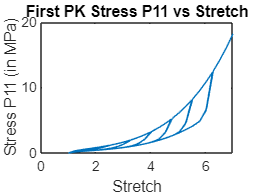

% P11 Stress from the other formula
P11 = zeros(asize, 1);

for i = 1:asize
    P11(i, 1) = 2*eta(i, 1) * (C1(i, 1)*(lambda(i, 1) - 1/(lambda(i, 1)^5)) + C2(i, 1)*(lambda(i, 1)^3 - 1/(lambda(i,1)^3)));
end
% P11 component of First Piola Kirchhoff Stress
plot(lambda, P11);
title("First PK Stress P11 vs Stretch");
ylabel("Stress P11 (in MPa)");
xlabel("Stretch")